# 1. Messung K_Sensor

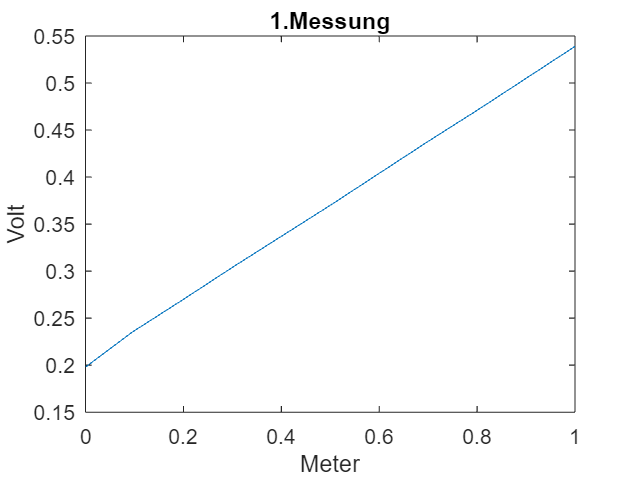

% u = Spannung 
% h = Wasserstand im Behälter

h1=[0 0.095 0.203 0.3 0.4 0.5 0.6 0.7 0.8 0.903 1]; %Einheit Meter
u1= [0.198 0.235 0.271 0.304 0.337 0.37 0.404 0.438 0.471 0.506 0.539]; % Volt
matrix1=[h1' u1'];
plot(h1,u1)
xlabel('Meter')
ylabel('Volt')
title('1.Messung')

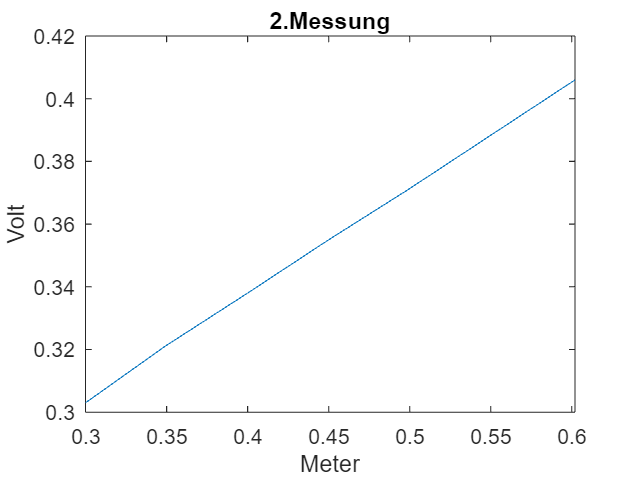





h2=[0.602 0.549 0.499 0.450 0.400 0.349 0.3]; % Meter
u2=[0.406 0.388 0.371 0.355 0.338 0.321 0.303]; % Volt
matrix2=[h2' u2'];
plot(h2,u2)
xlabel('Meter')
ylabel('Volt')
title('2.Messung')



%Mittelwert
h = h2; % in Kubikmeter/Sekunde
u = u2; %in Volt
plot(h, u,'ro', 'MarkerSize', 8, 'LineWidth', 2)
xlabel('Meter')
ylabel('Volt')
title('Auswertung der Messungen')

 hold on

% Lineare Näherung
pS = polyfit(h, u, 1);
K_Sensor = pS(1) % in 

K_Sensor = 0.3388

K_Sensor_Offset = pS(2)

K_Sensor_Offset = 0.2022

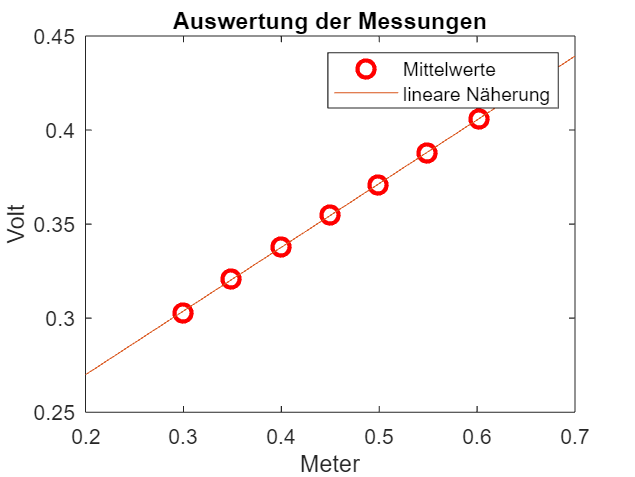

h_linear = linspace(0.2,0.7,30);
u_linear = polyval(pS,h_linear);
plot(h_linear,u_linear)
legend('Mittelwerte', 'lineare Näherung')